**Presentation of Timing Results from VHDL**

First we are going to obtain the timing results. Two vectors, one with

the start time, and other with the end times.

fileID = fopen('output_file.dat','r');
[values,count] = fscanf(fileID,['%f' ' ns']);
fclose(fileID);
starts = values(1:2:numel(values));
ends = values(2:2:numel(values));

Now we are going to present three different plots. 

- Duration of the multiplication

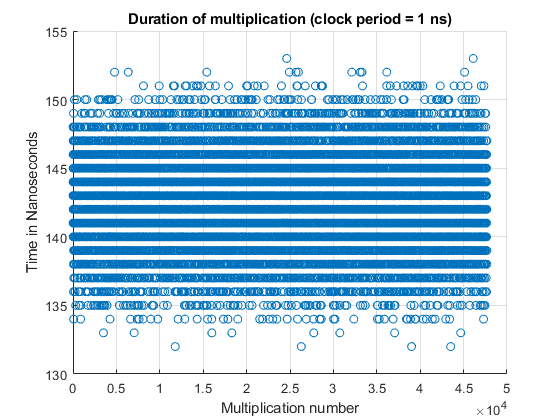

duration = zeros(1,numel(starts));
for i = 1:numel(starts)
    duration(i) = ends(i)-starts(i);
end
scatter(1:numel(duration),duration)
grid on
title('Duration of multiplication (clock period = 1 ns)')
xlabel('Multiplication number')
ylabel('Time in Nanoseconds')

% distances_mults = zeros(1,numel(starts)-1);
% for i = 1:numel(starts)-1
%     distances_mults(i) = starts(i+1)-starts(i);
% end
% plot(distances_mults)
% grid on
% title('Distances between multiplications')
% xlabel('Multiplication number')
% ylabel('Time in Nanoseconds')

The duration of the multiplication may leak the hamming weight of the second operand as it uses a double and add algorithm.

meanDuration = mean(duration);
stdDeviationDuration = std(duration);
disp(strcat("Mean duration is ",num2str(meanDuration)," ns"))

Mean duration is 142.3929 ns


disp(strcat("Standard deviation of duration is ",num2str(stdDeviationDuration)," ns"))

Standard deviation of duration is 2.8039 ns


- Distance between the end of one multiplication and the start of the other one

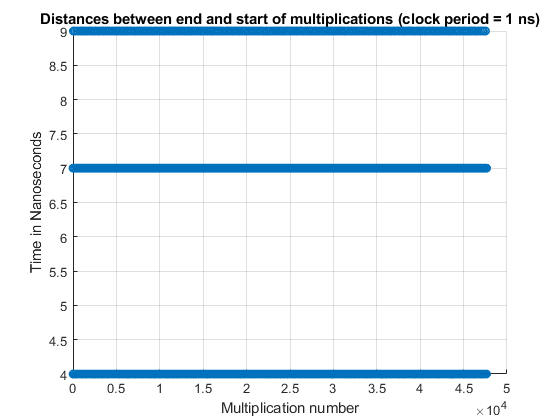

distances_end_start = zeros(1,numel(starts)-1);
for i = 1:numel(starts)-1
    distances_end_start(i) = starts(i+1)-ends(i);
end
scatter(1:numel(distances_end_start),distances_end_start)
% plot(distances_end_start,'-s','MarkerSize',10,...
%     'MarkerEdgeColor','b',...
%     'MarkerFaceColor',[0.5,0.5,0.5])
grid on
title('Distances between end and start of multiplications (clock period = 1 ns)')
xlabel('Multiplication number')
ylabel('Time in Nanoseconds')

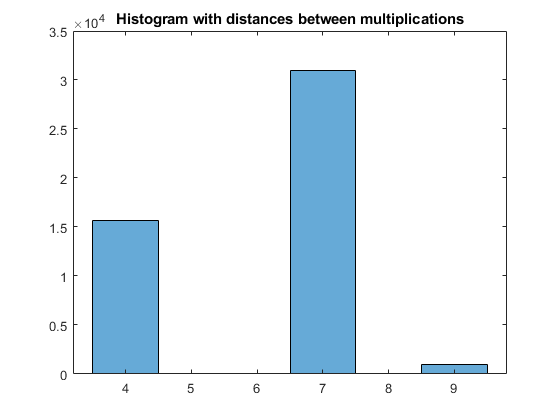



histogram(distances_end_start);

title('Histogram with distances between multiplications')